fs=48000;
f0=18000;

mode='data/';
fileFolder = fullfile(['receive/', mode]);
dirOutput = dir(fullfile(fileFolder,'*.wav'));
fileNames = {dirOutput.name};
file_name = fileNames{end}

file_name = 'google3record1644396829880.wav'

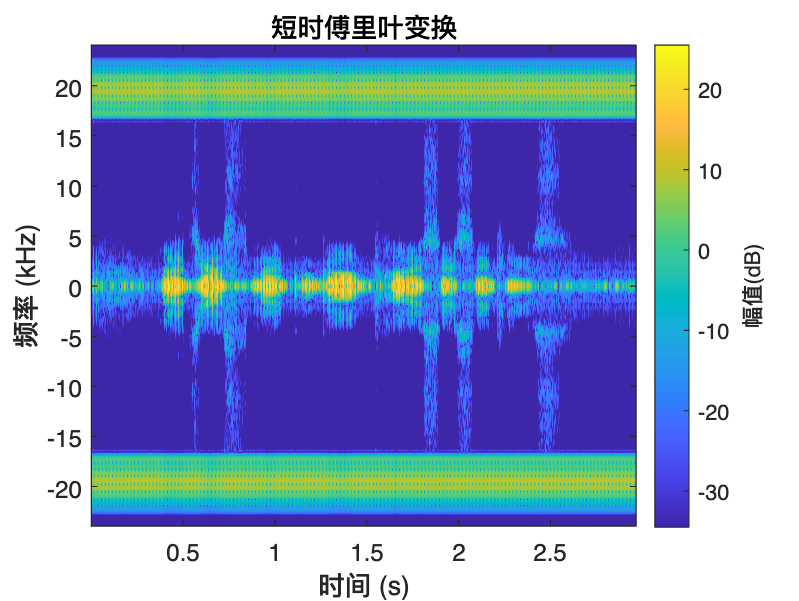



file=['receive/' , mode, file_name];

% data= importdata(file);
data=audioread(file);
stft(data, fs,"FFTLength", 512);

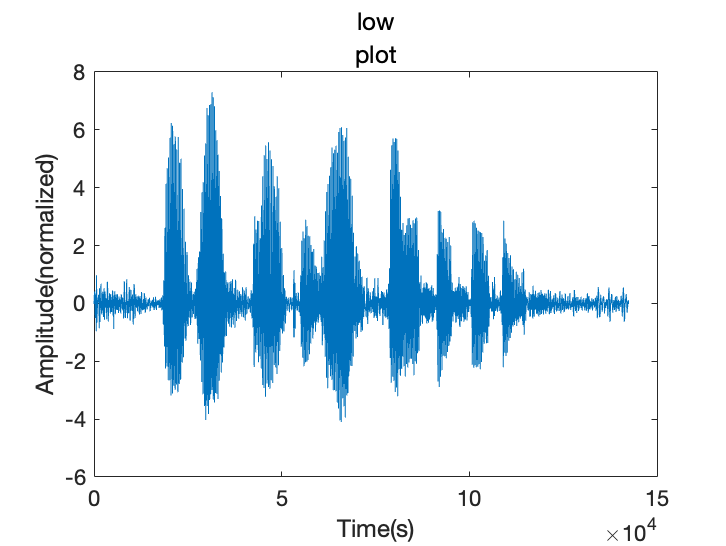

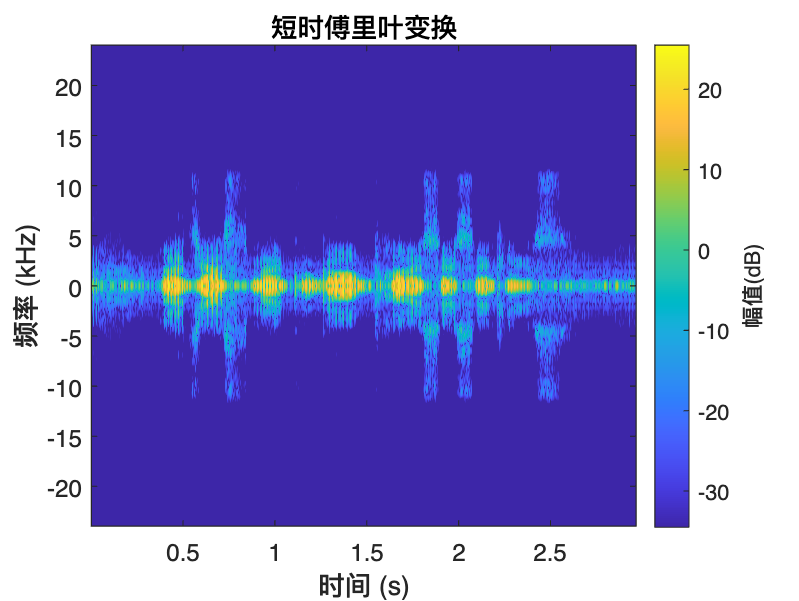

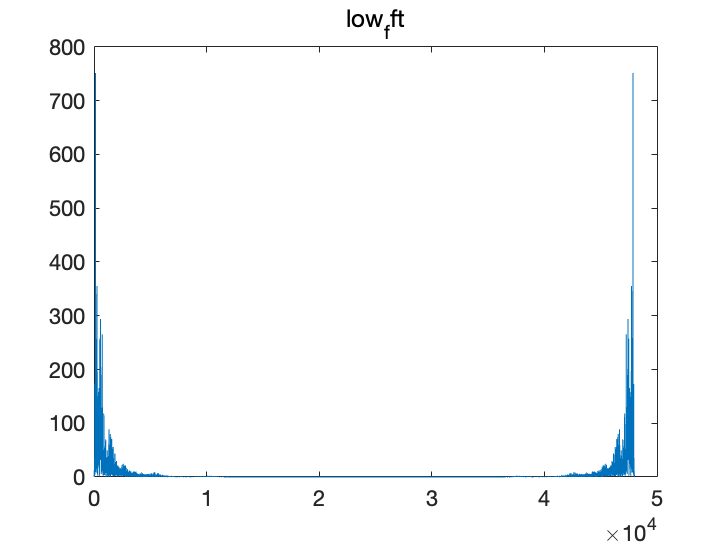

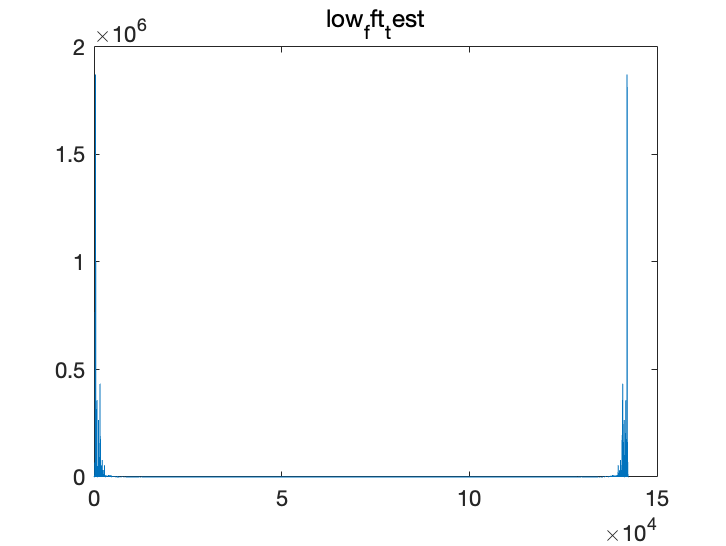

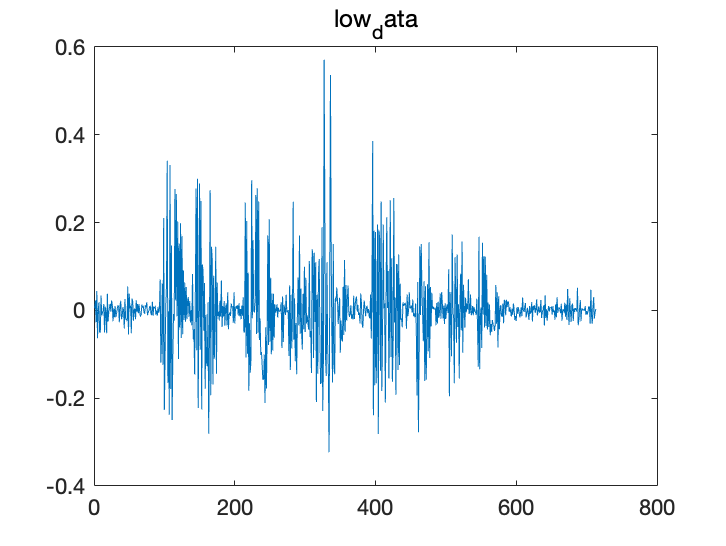

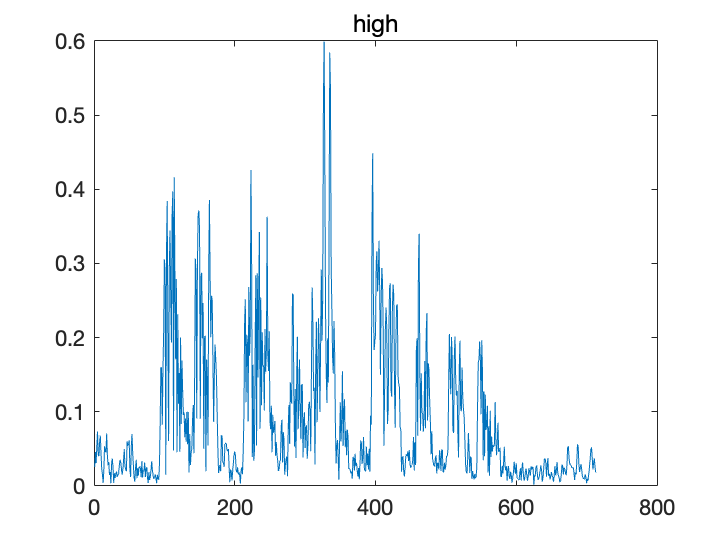

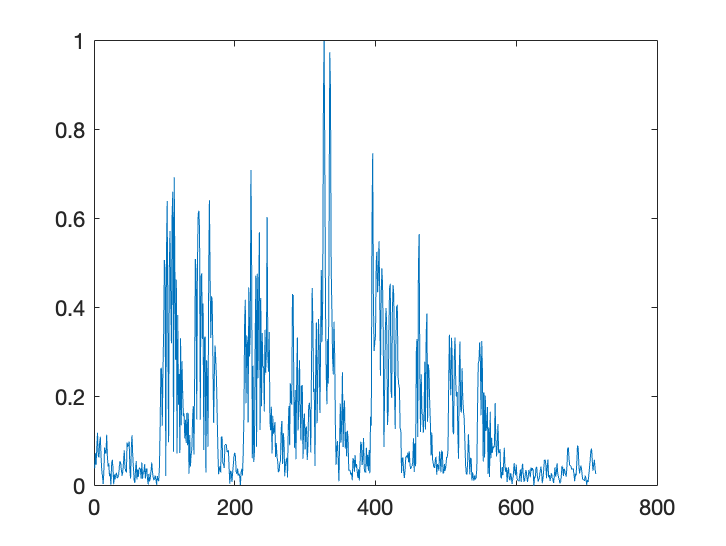

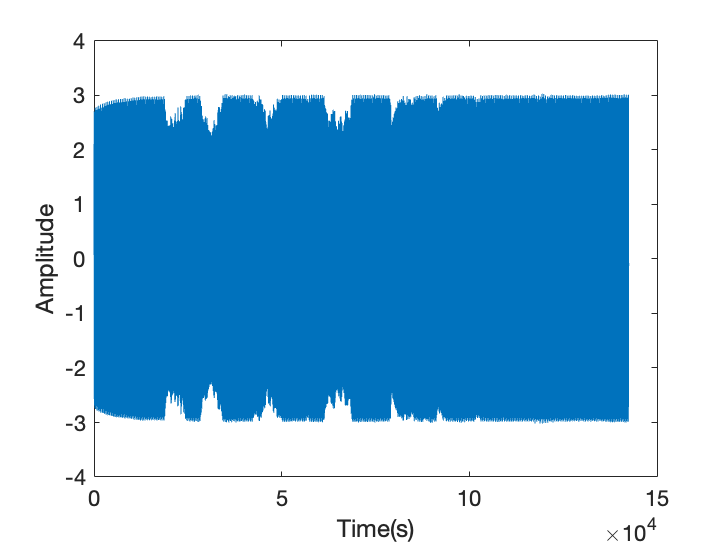

% data=data(28000:end-48000);
data=plot_highpass(data, fs);

% analysis_single(data, fs, f0);

% data=lowpass(data, 10000, fs);
% f0=pitch(data, fs, Method='SRH')
% figure;
% plot(f0)


% window=512;%滑动窗大小
% noverlap=256;%重叠样本数为100重叠99平移样本,每隔1个单位画一个框计算
% nfft=1024;
% spec_data=spectrogram(data, window, noverlap, nfft, fs, 'yaxis');  
% spec_data=abs(spec_data).*abs(spec_data);%取模
% spec_data=10*log10(spec_data);%取对数
% dim2freq=linspace(0,fs/2,size(spec_data,1));
% xlabels=0:1:size(spec_data,2);
% imagesc(xlabels,dim2freq,spec_data);%绘制语谱图
% colorbar();%显示colorbar()
% axis xy;%颠倒顺序
% hold on

% wlen=512;
% hop=256;
% h=hamming(wlen);
% f = linspace(17260, 17340, 257);
% spectrogram(data, h, 256, f, fs);
% imagesc(t, f, 20*log10((abs(s))));xlabel('Samples'); ylabel('Freqency');
% colorbar;



% win_len=512;
% win=rectwin(win_len);
% overlap=256;
% f=enframe(power, win, overlap)
% figure;
% plot(f);
% title 'ming';
% getIQ(data);

% high_data=highpass(data, 10000, fs);
% % low_data=lowpass(data, 8000, fs)
% plot(high_data);
% stft(high_data,fs);
% win_len=512;
% win=rectwin(win_len);
% overlap=256;
% f=enframe(high_data, win, overlap);
% plot(f);
% 
% data=plot_highpass(data, fs);
% analysis_single(data, fs, f0);




